format longg
CP = py.importlib.import_module("CoolProp.CoolProp");

zeta_ind = 0.2;
zeta_boj_90 = 0.30;
zeta_boj_135 = zeta_boj_90 * 1.5;
zeta_boj_180 = zeta_boj_90 * 2;
zeta_buffer = 1 + 0.25;
zeta_flow = 1;
zeta_filter = 3;
zeta_skue = zeta_buffer;
% zeta_epv = 69


zeta_total = zeta_ind + 5*zeta_boj_90 + 3*zeta_boj_135 + zeta_boj_180...
    + zeta_buffer + zeta_flow + zeta_filter + zeta_skue %+ zeta_epv

zeta_total =                      10.15



r_i = 0.046;
r_y = 0.0485;

% L_k_i = 2 * r_i ;
% h = 1.27;
% A_cyl = h * L_k_i * pi

A_cyl =          0.367063685645431


% A_bund = pi * r_i^2

A_bund =          0.006647610054996


% A_i = A_cyl + A_bund

A_i =          0.373711295700427


# **Område 3**

**For væske**

L = 1.585 %1.95; %m

L =                      1.585


t = 0.00080; %m
d = 0.00794 - 2*t %m

d =                    0.00634


d_i = 0.008 - 2*0.0002 %m diameteren ud af kondensatoren

d_i =                     0.0076




% c_foer_kond = 5.24 % m/s
c_efter_kond = 0.1495 % m/s

c_efter_kond =                     0.1495



c_i = c_efter_kond % 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren

c_i =                     0.1495



% c * d^2 = d_i^2 * c_i %countinuitetsligningen
c = d_i^2 * c_i / d^2

c =          0.214827493556509



rho_fluid = CP.PropsSI('D', 'T', 30 + 273.15, 'P', 886810, 'R134a') %1186.61436781861; %kg/m^3 

rho_fluid =           1188.24518242834






nu = CP.PropsSI('V', 'T', 30 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       0.000183563655795652


Re = c * d / nu 

Re =           7.41980379092301



% Re < 2300 dermed laminart flow


% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =           8.62556501538412



Delta_p_ror = lambda * L * c^2 * rho_fluid / (d * 2)

Delta_p_ror =           59126.6605799141



Delta_p_enkelt = zeta_total * (rho_fluid * c^2)/ 2

Delta_p_enkelt =           278.305527262623


**For gas**

% c = 2.26638867101572; %m/s    
% rho_vape = 31.2106794247976; %kg/m^3 
% 
% 
% 
% L = 6.7 %1.95%1.95 %m
% t = 0.00080; %m
% d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m
% 
% nu = CP.PropsSI('V', 'T', 30 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  
% Re = c * d / nu 
% 
% % Re < 2300 dermed laminart flow
% 
% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d
% 
% lambda = 64/Re  % <-----------
% 
% Delta_p_ror = lambda * L * c^2 * rho_vape / (d * 2)

% Delta_p = zeta_total * (rho * c^2)/ 2


# Fordamperen

## Gas / væske

c_for_ford = 8.157 %m/s

c_for_ford =                      8.157




d2 = 0.00952 - 2*t

d2 =                    0.00792



c2 = c_for_ford%c_uden_ford % c_for_ford %c1 * rho1 * d1^2 / (d2^2 * rho_for )

c2 =                      8.157



L = 6.7 %1.95%1.95 %m

L =                        6.7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'H', 241463, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       9.79327724992818e-06


rho = CP.PropsSI('D', 'H', 241463, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

rho =           21.0650463334632




K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879


% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



% lambda = 64/Re  % <-----------
lambda = 0.035

lambda =                      0.035


Re = c2 * d2 / nu

Re =           6596.71306665741



Delta_p_ror = lambda * L * c2^2 * rho / (d2 * 2)

Delta_p_ror =           20749.6613514324



% Delta_p = zeta_total * (rho * c^2)/ 2'

## Gas

c_efter_ford = 25.78 %m/s

c_efter_ford =                      25.78



d2 = 0.00952 - 2*t

d2 =                    0.00792



c2 = c_efter_ford%c_uden_ford % c_for_ford %c1 * rho1 * d1^2 / (d2^2 * rho_for )

c2 =                      25.78



L = 6.7 %1.95%1.95 %m

L =                        6.7


t = 0.00080; %m
d = 0.00952 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                    0.00792



nu = CP.PropsSI('V', 'H', 389428, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

nu =       1.01442809792569e-05


rho = CP.PropsSI('D', 'H', 389428, 'P', 132700, 'R134a') % |not_imposed %m^2/s  

rho =           6.66883074573702




K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879


% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %rukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000378787878787879



% lambda = 64/Re  % <-----------
lambda = 0.025

lambda =                      0.025


Re = c2 * d2 / nu

Re =           20127.3604721226



Delta_p_ror = lambda * L * c2^2 * rho / (d2 * 2)

Delta_p_ror =            46867.863388616


# For Kondensatoren

**For væske**

L = 19.71 %1.95; %m

L =                      19.71


t = 0.0002; %m
d = 0.008 - 2*t %m diameteren ud af kondensatoren

d =                     0.0076



% c_fluid = 0.0596112201077589; %m/s hastigheden da fluidet kommer ud af kondensatoren


c_middel = 2.676

c_middel =                      2.676


c_efter_kond = 0.1495 % m/s

c_efter_kond =                     0.1495


c = c_middel% c_efter_kond

c =                      2.676



rho_middel = 162.8964

rho_middel =                   162.8964


rho_fluid = rho_middel % CP.PropsSI('D', 'T', 35 + 273.15, 'P', 886810, 'R134a') %1186.61436781861; %kg/m^3 

rho_fluid =                   162.8964




nu = CP.PropsSI('V', 'T', 35 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       1.21322664453747e-05


Re = c * d / nu 

Re =           1676.32322382381



% Re < 2300 dermed laminart flow

% K_s = 0.003 * 10^(-3); %rukne rør af kobbe
% reltativ_rughed = K_s/ d

lambda = 64/Re  % <-----------

lambda =         0.0381787945728102



Delta_p_ror = lambda * L * c^2 * rho_fluid / (d * 2)

Delta_p_ror =           57749.5963843647


**For gas**

c_foer_kond = 5.24 % m/s

c_foer_kond =                       5.24


c_middel = 2.676

c_middel =                      2.676


c_vape = c_middel % c_foer_kond %2.26638867101572; %m/s   

c_vape =                      2.676


 
% rho_vape = 31.2106794247976; %kg/m^3 
rho_middel = 162.8964

rho_middel =                   162.8964


rho_vape = rho_middel %CP.PropsSI('D', 'T',  82.25 + 273.15, 'P', 886810, 'R134a')

rho_vape =                   162.8964



L = 19.71 %1.95%1.95 %m

L =                      19.71


t = 0.0002; %m
d = 0.008 - 2*t %m %0.00794 - 2*t %m % fordamper er 0.00952 - 2*t %m

d =                     0.0076



nu = CP.PropsSI('V', 'T',  (82.25 + 23)/2 + 273.15, 'P', 886810, 'R134a') % |not_imposed %m^2/s  

nu =       1.28961382606556e-05


Re = c_vape * d / nu 

Re =             1577.030238738


(82.25 + 23)/2

ans =                     52.625


% Re < 2300 dermed laminart flow

K_s = 0.003 * 10^(-3); %trukne rør af kobbe
reltativ_rughed = K_s/ d

reltativ_rughed =       0.000394736842105263



lambda = 64/Re  % <-----------

lambda =         0.0405826080108745



Delta_p_ror = lambda * L * c_vape^2 * rho_vape / (d * 2)

Delta_p_ror =           61385.6267353698


enektl modstande


zeta_boj_90 = 0.30;

zeta_boj_180 = zeta_boj_90 * 2;



zeta_total = zeta_boj_180 * 56

zeta_total =                       33.6



Delta_p_fluid = zeta_total * (rho_fluid * c^2)/ 2

Delta_p_fluid =           19597.1531428915


Delta_p_vape = zeta_total * (rho_vape * c_vape^2)/ 2

Delta_p_vape =           19597.1531428915


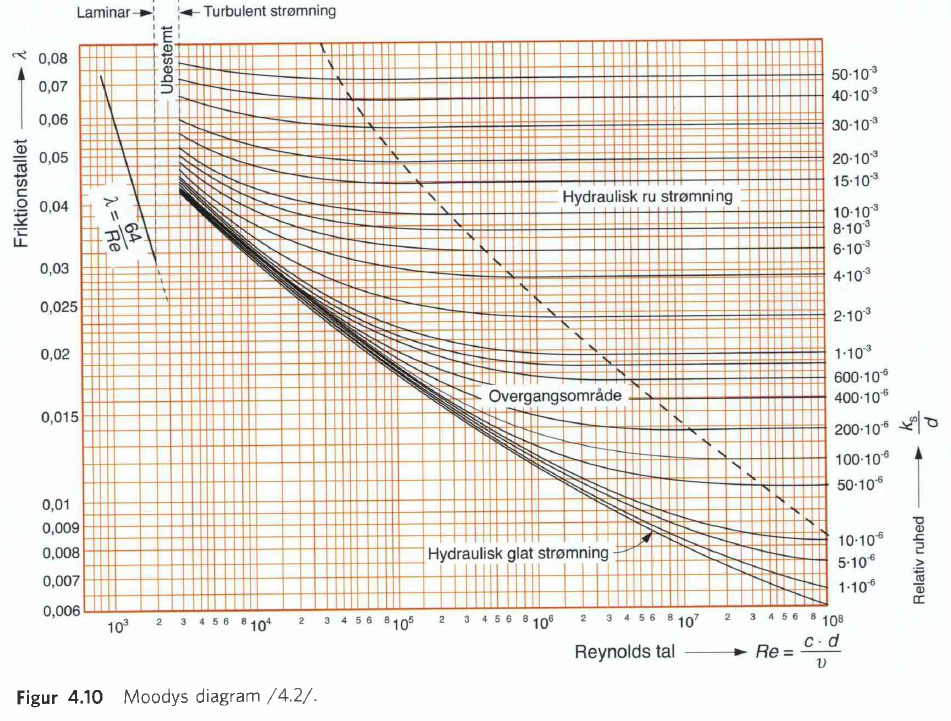

Video til coolprop

[https://www.youtube.com/watch?v=XvR10Fjph7U](https://www.youtube.com/watch?v=XvR10Fjph7U) 

For coolprop

[https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png](https://media.discordapp.net/attachments/904796150694031402/1105756331090120754/image.png)